# Exposure duration increases the size of the flare

Figure 5 calculation showing flare increasing with exposure duration.  Similar to the earlier flare image, but this time with a complex nighttime driving scene.

ieInit;

## Load the light groups

If the file is not already present, use ieWebGet to download from the Stanford Digital Repository.  

The URL for the repository is:  https://purl.stanford.edu/bt316kj3589

imageID = '1114031438';

lgt = {'headlights','streetlights','otherlights','skymap'};
destPath = fullfile(isethdrsensorRootPath,'data',imageID);

scenes = cell(numel(lgt,1));
for ll = 1:numel(lgt)
    thisFile = sprintf('%s_%s.exr',imageID,lgt{ll});
    destFile = fullfile(destPath,thisFile);
    if ~exist(destFile,"file")
        ieWebGet('deposit name','isethdrsensor-paper',...
            'deposit file',fullfile('data',imageID,thisFile),...
            'download dir',fullfile(isethdrsensorRootPath,'data',imageID),...
            'unzip',false);
    end
    scenes{ll} = piEXR2ISET(destFile);
end

*** Downloading data/1114031438/1114031438_headlights.exr from ISETHDRSensor on SDR ... 
*** File is downloaded! 
*** Downloading data/1114031438/1114031438_streetlights.exr from ISETHDRSensor on SDR ... 
*** File is downloaded! 
*** Downloading data/1114031438/1114031438_otherlights.exr from ISETHDRSensor on SDR ... 
*** File is downloaded! 
*** Downloading data/1114031438/1114031438_skymap.exr from ISETHDRSensor on SDR ... 
*** File is downloaded! 


## Night parameters

These weights produce a nighttime scene.  We then denoise.

wgts_night = [3.0114    0.0378    0.0498    0.0030];
scene = sceneAdd(scenes, wgts_night);
thisScene = piAIdenoise(scene);

Denoised in: 17.347


## Create the optics

Any optics with flare will work the same.

[oi,wvf] = oiCreate('wvf');
wvf = wvfSet(wvf, 'spatial samples',512);

[aperture, params] = wvfAperture(wvf,'nsides',0,...
    'dot mean',0, 'dot sd',0, 'dot opacity',0.5,'dot radius',5,...
    'line mean',0, 'line sd', 0, 'line opacity',0,'linewidth',2);
oi = oiCompute(oi, thisScene,'aperture',aperture,'crop',true,'pixel size',3e-6);

## ON sensor simulation

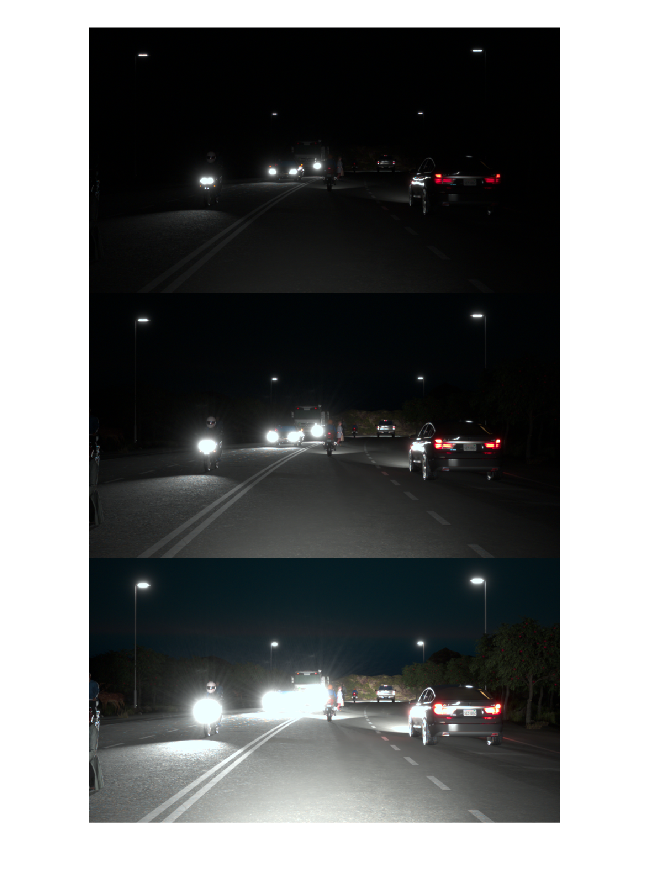

sensorRGB = sensorCreate('ar0132at',[],'rgb');
sensorRGB = sensorSet(sensorRGB,'match oi',oi);
sensorRGB = sensorSet(sensorRGB,'exp time',0.005);
sensor    = sensorCompute(sensorRGB, oi);
img = cell(3,1);

ip = ipCreate;
ip = ipCompute(ip,sensor);
img{1} = ipGet(ip,'srgb');
% ipWindow(ip,'gamma',0.5);

sensorRGB = sensorSet(sensorRGB,'exp time',0.0405);
sensor = sensorCompute(sensorRGB, oi);

ip = ipCompute(ip,sensor);
img{2} = ipGet(ip,'srgb');

% ipWindow(ip,'gamma',0.5);

sensorRGB = sensorSet(sensorRGB,'exp time',0.3242);
sensor = sensorCompute(sensorRGB, oi);
ip = ipCompute(ip,sensor);
img{3} = ipGet(ip,'srgb');

% ipWindow(ip,'gamma',0.5);
montage(img,'Size',[3,1]);

## Use the split pixel in Figure 07

This is from Figure 7 in the paper.

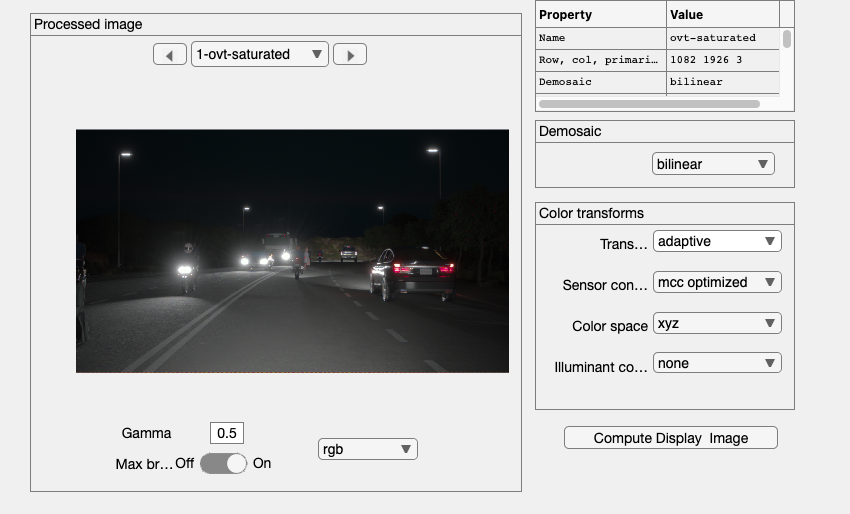

expTime = 342e-3;   
satLevel = .95;
pixelSize = [3 3]*1e-6;
sensorSize = [1082 1926];

arrayType = 'ovt'; 

% The OVT design is a 3-capture (two large PD captures and one small PD).
sensorArray = sensorCreateArray('array type',arrayType,...
    'pixel size same fill factor',pixelSize,...
    'exp time',expTime, ...
    'quantizationmethod','analog', ...
    'size',sensorSize);

[sensorSplit,sensorArraySplit] = sensorComputeArray(sensorArray,oi,...
    'method','saturated', ...
    'saturated',satLevel);

ip = ipCreate;
ip = ipCompute(ip,sensorSplit,'hdr white',true);
ipWindow(ip,'gamma',0.5);